clear
clc
close all
%Distinct nulls, maybe M>N
%TSLDMA-II
N = 3;                          % Order of ideal function
f = 1e3;                        % Signal frequency (Hz)
d = 0.01;                       % Microphone spacing (m)
c = 343;                        % Speed of sound (m/s)
M = N + 1;                      % Number of microphones
xs = cosd(45);                  % Steering angle
x = [xs cosd(100) cosd(150)]'   % Temporary null vector

x =     0.7071
   -0.1736
   -0.8660


epsi = diag(0:N);
Q = [(x(1).^(0:N)); (x(1).^(0:N)*epsi); (x(2).^(0:N)); (x(3).^(0:N))]

Q =     1.0000    0.7071    0.5000    0.3536
         0    0.7071    1.0000    1.0607
    1.0000   -0.1736    0.0302   -0.0052
    1.0000   -0.8660    0.7500   -0.6495


a = Q\eye(length(Q),1)          % Inverse with constraint function

a =     0.2445
    1.4979
    0.2966
   -1.2782


xN = - a(end-1)/a(end) - sum(x(2:end))

xN = 1.2717


x = [x; xN]                     % Determined null vector

x =     0.7071
   -0.1736
   -0.8660
    1.2717



D = [exp((-1i*2*pi*f*d*(0:M-1)*x(1))/c); exp((-1i*2*pi*f*d*(0:M-1)*x(2))/c); ...
    exp((-1i*2*pi*f*d*(0:M-1)*x(3))/c); exp((-1i*2*pi*f*d*(0:M-1)*x(4))/c);]

D =    1.0000 + 0.0000i   0.9916 - 0.1292i   0.9666 - 0.2562i   0.9254 - 0.3789i
   1.0000 + 0.0000i   0.9995 + 0.0318i   0.9980 + 0.0636i   0.9955 + 0.0953i
   1.0000 + 0.0000i   0.9874 + 0.1580i   0.9501 + 0.3120i   0.8889 + 0.4582i
   1.0000 + 0.0000i   0.9730 - 0.2309i   0.8934 - 0.4492i   0.7656 - 0.6434i



h = D\eye(length(D),1)          % Filter weights

h = 1.0e+02 *

   0.3598 - 2.0587i
  -1.1496 + 6.0788i
   1.2392 - 6.0612i
  -0.4470 + 2.0415i



% Input
angRes = 360;
thetas = linspace(0,2*pi,angRes);
Y = exp((-1i*2*pi*f*d*(0:M-1).*cos(thetas(:)))/c)'

Y =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   0.9833 + 0.1822i   0.9833 + 0.1821i   0.98


output = h'*Y

output =    0.7568 + 0.0610i   0.7571 + 0.0610i   0.7579 + 0.0610i   0.7592 + 0.0609i   0.7611 + 0.0609i   0.7635 + 0.0608i   0.7664 + 0.0606i   0.7698 + 0.0605i   0.7737 + 0.0603i   0.7780 + 0.0601i   0.7828 + 0.0598i   0.7881 + 0.0595i   0.7937 + 0.0592i   0.7998 + 0.0588i   0.8062 + 0.0584i   0.8130 + 0.0579i   0.8200 + 0.0573i   0.8274 + 0.0567i   0.8349 + 0.0560i   0.8428 + 0.0552i   0.8507 + 0.0544i   0.8589 + 0.0534i   0.8671 + 0.0524i   0.8755 + 0.0513i   0.8838 + 0.0501i   0.8922 + 0.0488i   0.9006 + 0.0473i   0.9088 + 0.0458i   0.9170 + 0.0442i   0.9250 + 0.0424i   0.9327 + 0.0406i   0.9403 + 0.0386i   0.9476 + 0.0365i   0.9546 + 0.0343i   0.9612 + 0.0320i   0.9674 + 0.0295i   0.9732 + 0.0270i   0.9785 + 0.0243i   0.9833 + 0.0216i   0.9876 + 0.0187i   0.9913 + 0.0157i   0.9944 + 0.0126i   0.9968 + 0.0095i   0.9986 + 0.0063i   0.9997 + 0.0030i   1.0000 - 0.0004i   0.9996 - 0.0039i   0.9984 - 0.0073i   0.9964 - 0.0109i   0.9936 - 0.0144i


bp = sqrt(power(real(output),2)+power(imag(output),2))

bp =     0.7593    0.7595    0.7603    0.7617    0.7635    0.7659    0.7688    0.7722    0.7760    0.7803    0.7851    0.7903    0.7959    0.8019    0.8083    0.8150    0.8220    0.8293    0.8368    0.8446    0.8525    0.8605    0.8687    0.8770    0.8853    0.8936    0.9018    0.9100    0.9180    0.9259    0.9336    0.9411    0.9483    0.9552    0.9617    0.9678    0.9736    0.9788    0.9835    0.9878    0.9914    0.9944    0.9969    0.9986    0.9997    1.0000    0.9996    0.9984    0.9965    0.9937


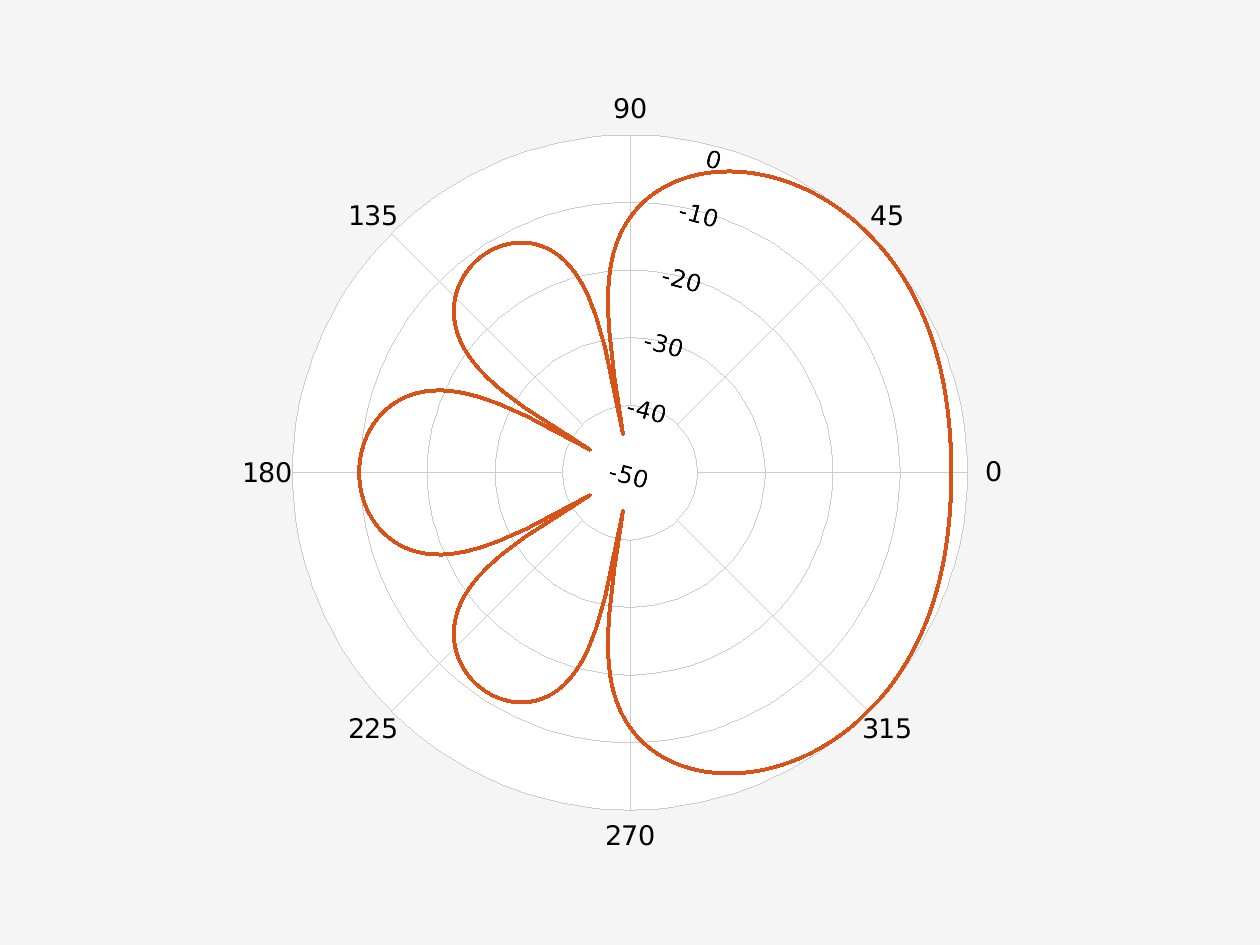


%figure() % For eksport
polarpattern(thetas*180/pi,20*log10(bp)', 'AngleResolution', 45, 'LineWidth', ...
    3, 'MagnitudeLim', [-50 0], 'ColorOrderIndex', 2)


[~, maxAng] = max(bp);
[~, minAng] = min(bp);
fprintf('Maximum: %d°\n', maxAng*360/angRes)

Maximum: 46°


fprintf('Minimum: %d°\n', minAng*360/angRes)

Minimum: 101°
